## Load Station Aloha Temperature data

T: temp (°C), t: time, z: depth (m)

load HOTS_Temp.mat

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

nt = length(t);
nz = length(z);

## Remove time average

Td = detrend(T',0)';

Covariance matrix - Last time we computed the covariance matrix as C = 1/(nt-1)*(Td*Td').  Td has dimensions nz by nt, so in this form the covariance is computed summed over time, and C has dimension nz by nz, and the eigenvectors have the dimension time, and the PCs have the dimension space.  For convenience, let's drop the 1/(nt-1), which will not affect the computation of the eigenvectors or PCs (it does affect the eignvalues, but we're only concerned about the percent variance of each mode, which is unaffected by the normalization).

More commonly when the data matrix (Td) has # of rows  > # of columns (in our case nz > nt), the covariance marix is formed as C = Td'*Td.  The eigenvectors then have the smaller dimension, in this case time, and the PCs have the larger space dimension.  

## C2 = Td'*Td  compared to C = Td*Td'

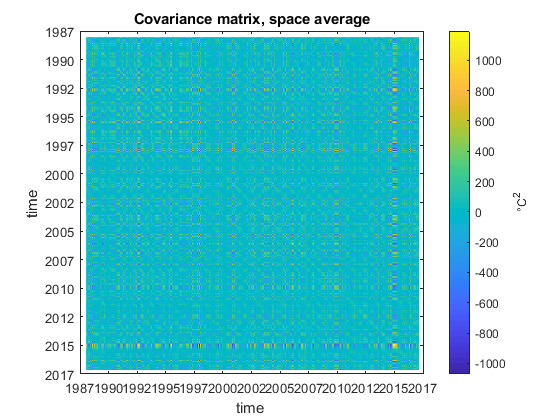

C2 = Td'*Td;

figure (1)
clf
imagesc(t,t,C2)
cb = colorbar;
ylabel(cb,'°C^2')
ylabel('time ')
xlabel('time ')
datetick('x')
datetick('y')
title('Covariance matrix, space average')
axis('square')

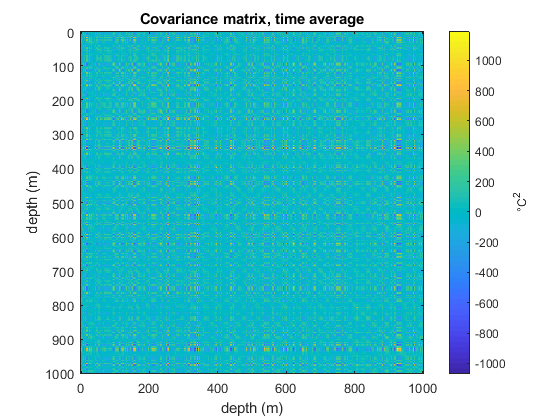


C = Td*Td';

figure (2)
clf
imagesc(z,z,C2)
cb = colorbar;
ylabel(cb,'°C^2')
ylabel('depth (m)')
xlabel('depth (m)')
title('Covariance matrix, time average')
axis('square')

## Compute EOF and plot percent variance of each mode using C2

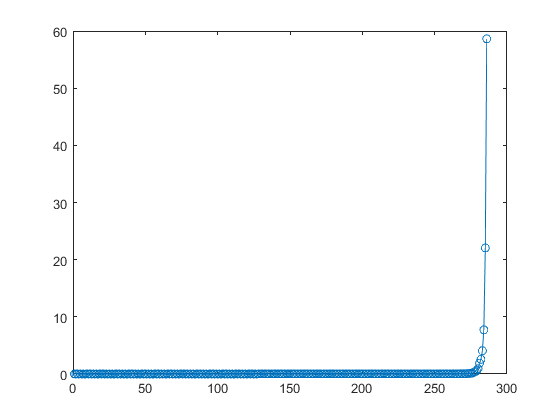

clear lambda
[e,lambda] = eig(C2);
lambda = diag(lambda);
pvar = lambda/sum(lambda)*100;

figure (4)
plot(pvar,'o-')

## Reverse the order of the modes if necesary

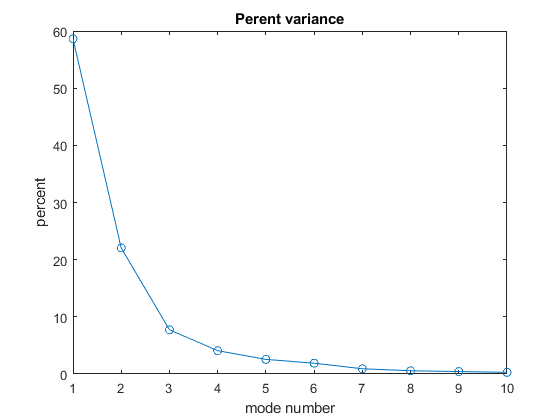

e = fliplr(e);
lambda = flipud(lambda);
pvar = flipud(pvar);

figure (5)
plot(pvar,'o-')
xlim([1 10])
title('Perent variance')
xlabel('mode number')
ylabel('percent')

## Plot EOFs, now time series

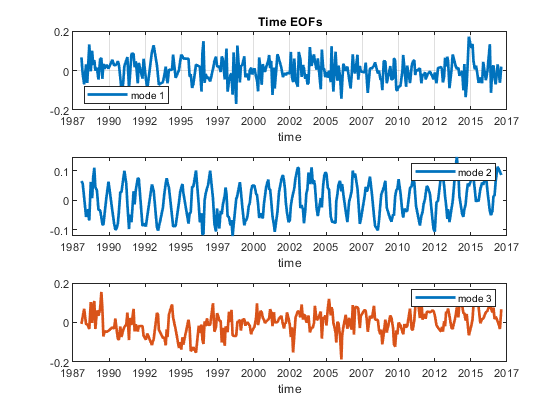

figure (6)
hold on
subplot(3,1,1)
plot(t, e(:,1),'LineWidth',2)
datetick
xlabel('time')
legend('mode 1')
title('Time EOFs')
grid on
legend('location','SouthWest')
subplot(3,1,2)
plot(t, e(:,2),'LineWidth',2)
legend ('mode 2')
datetick
xlabel('time')
subplot(3,1,3)
plot(t, e(:,3),'LineWidth',2)
datetick
xlabel('time')
legend('mode 3')
hold off

These are now the normalized version of the temporal expansin. The last time these carried the units and this time the next step contains the units inside them. Either way when you combine them they will be the same. 

## Plot PCs, now depth profiles.   Compute PCs as A = Td*e;

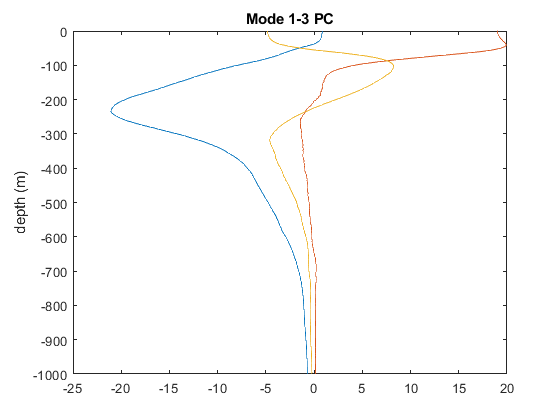

A = Td*e;
figure (7)
plot(A(:,1:3),-z)
ylabel('depth (m)')
title('Mode 1-3 PC')

This is different from the eigen values found last time because the deg C needs to be reflected in the temporal expansion (hence the larger units)...In this plot we see what was our TEMP eigen values it has now become the PC (time expansion) of the TIME 

The flipping of the direction doesnt matter because a NEGATIVE(time series)*NEGATIVE(PC expansion) will result in the same outcome as before if both positive

This one (compared to the EOF of the last one) is NOT normalized to = 1. These are the PC that **must carry the unit **and are SCALED to the variance they explain. These aren't normalized equally, they reflect how important they are.  

THere is ambiguity in the + or - signs. If you want mode 1 to have a positive expression, the time expansion is going to need to be flipped in sign as well. 